## Aproximación de pi

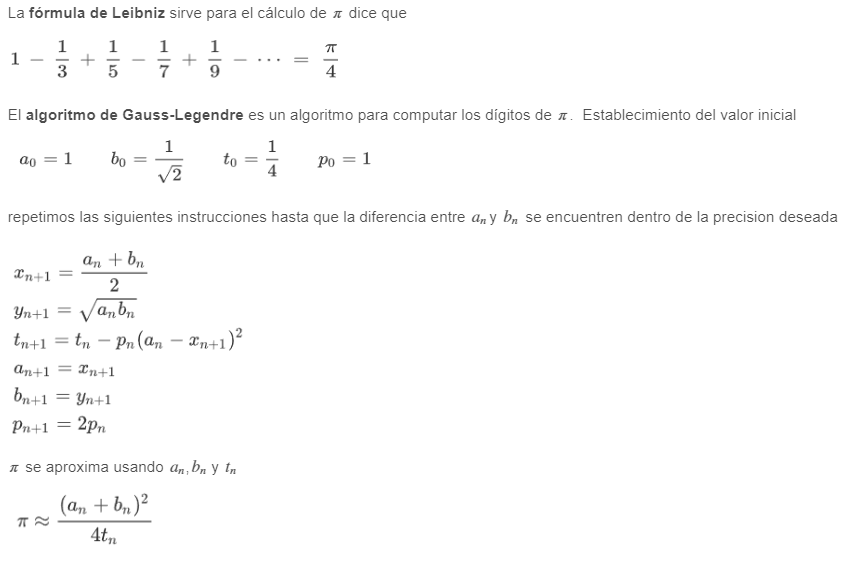

%%%%%%%%%%%%% halle las aproximaciones de pi y los errores asociados %%%%%%%%%%%%%



%%%%%%%%%%%%% funciones a completar %%%%%%%%%%%%%

function pi_ap = leibniz_pi(n)
% n: número de iteraciones
% pi_ap: valor aproximado de pi
    pi_ap = 0;  
    
    for i = 0:n
        term = (-1)^i / (2*i + 1);  
        pi_ap = pi_ap + term; 
    end
    
    % complete aquí
    pi_ap = 4 * pi_ap; 
end

format long;
a0 = 1;
b0 = 1 / sqrt(2);
t0 = 1 / 4;
p0 = 1;


m = 5;

for i = 1:m
    x1 = (a0 + b0) / 2;
    y1 = sqrt(a0 * b0);
    t1 = t0 - p0 * (a0 - x1)^2;

    % preparamos la siguiente iteración
    t0 = t1;
    a0 = x1;
    b0 = y1;
    p0 = 2 * p0;
end

((a0 + b0)^2 / (4 * t0))
pi